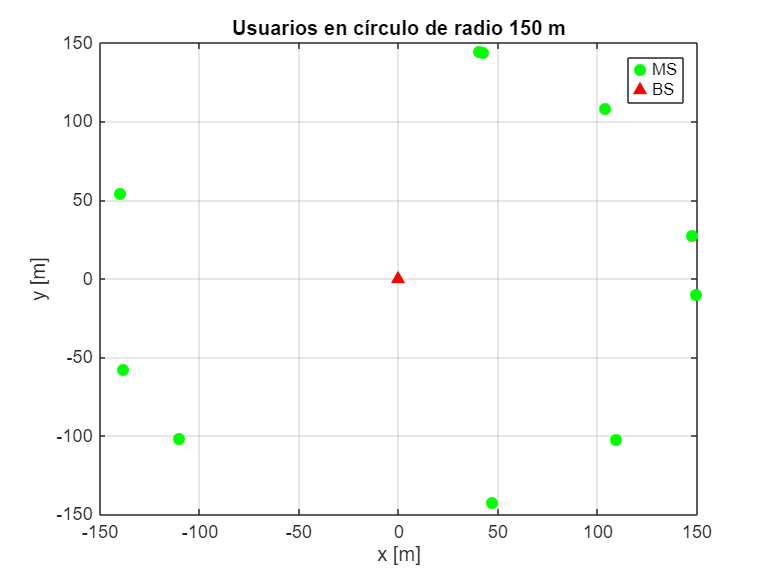

clear all; clc;


% ---------------------------------------------
% Parámetros del sistema
% ---------------------------------------------

B = 10*10^6;            % Ancho de banda de 10 MHz
f = 1.8*10^9;           % Frecuencia portadora de 1.8 GHz
Ptx = 20;               % Potencia de transmisión en vatios (20 W)
num_muestras = 960000;  % Número total de muestras a simular inicialmente
N0 = 10^-20;            % Densidad espectral de ruido (W/Hz)
sigma_sh = 1.5;         % Desviación típica del shadowing log-normal (dB)
fd_values = [5 50 120]; % Tres valores posibles de frecuencia de Doppler (baja, media, alta)
ts = 1/B;               % Tiempo de símbolo = inverso del ancho de banda
M = 16;                 % Tamaño de la modulación (16QAM)

% ---------------------------------------------
% Ubicación de los usuarios y la estación base
% ---------------------------------------------

Pos_BS = 0 + 1i * 0;    % Estación base ubicada en el origen (coordenadas complejas)

K = 10;                 % Número total de usuarios móviles

% ---------------------------------------------
% Opción 2: usuarios distribuidos en un círculo de 150 m
% ---------------------------------------------

lado_x2 = 150; lado_y2 = 150;
option2 = 2; % Código para modo circular
Pos_MS2 = Calc_Pos_MS(option2, K, lado_x2, lado_y2, 0, 0);

% -------------------------------
% Visualización
figure;
plot(real(Pos_MS2), imag(Pos_MS2), 'go', 'MarkerFaceColor', 'g');
hold on;
plot(real(Pos_BS), imag(Pos_BS), 'r^', 'MarkerFaceColor', 'r');
title('Usuarios en círculo de radio 150 m');
xlabel('x [m]'); ylabel('y [m]');
grid on; legend('MS','BS');

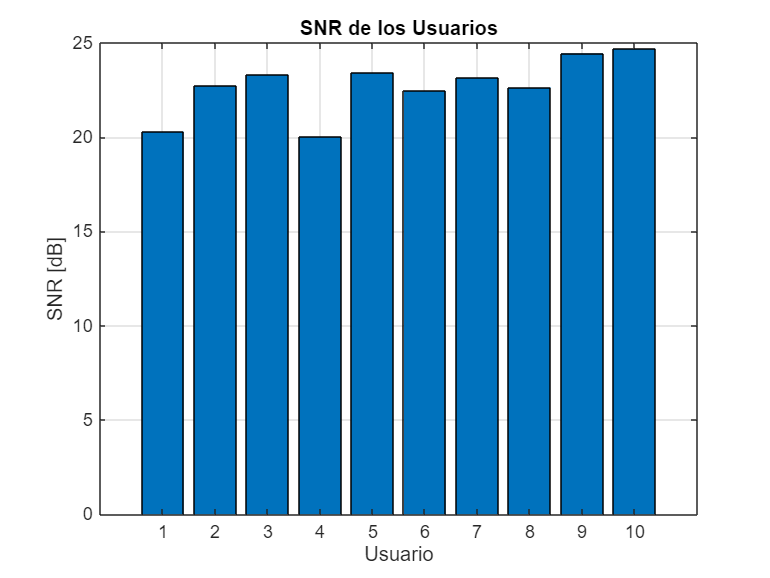


% ---------------------------------------------
% Cálculo inicial de la SNR de cada usuario
% ---------------------------------------------

SNRs = zeros(K, 1); % Vector para almacenar la SNR de cada usuario

for k = 1:K
    dist = abs(Pos_BS - Pos_MS2(k)); % Distancia entre BS y usuario k
    SNRs(k) = calcular_SNRs(Pos_BS, Pos_MS2(k), Ptx, B, f, sigma_sh, N0); % Cálculo de SNR
end


% ---------------------------------------------
% Visualización de las SNRs de los usuarios
% ---------------------------------------------
figure;
bar(SNRs); % Representación gráfica en barras
title('SNR de los Usuarios');
xlabel('Usuario');
ylabel('SNR [dB]');
grid on;

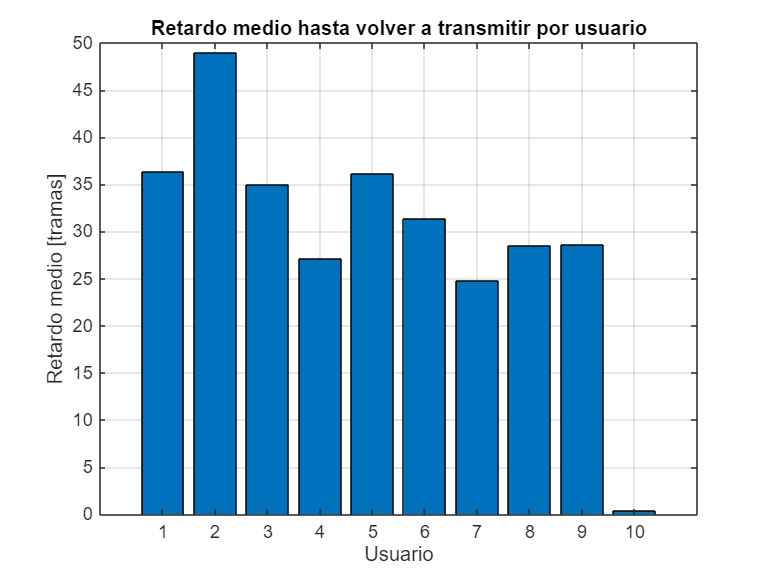

% ---------------------------------------------
% Parámetros de simulación y Scheduler
% ---------------------------------------------

num_muestras = 9600; % Número real de muestras útiles
SNR_avg = mean(SNRs); % SNR media de todos los usuarios
delay_vector = zeros(1, K); % Inicializa el vector de retardos
num_tramas = num_muestras / 32; % Cada trama representa 32 símbolos

%Casos con algoritmo de utilidad para las distintas frecuencias Doppler
algoritmo = 'utilidad'; % Algoritmo de planificación

% --- Simulación con frecuencia de Doppler = 5 Hz ---
SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(1), num_muestras, ts);
SNR_instantanea = SNR_instantanea(:, 1:32:end); % Tomar columnas cada 32 muestras

[selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);

plotMeanDelay(retardos);

disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

Usuario seleccionado final: 2      Vector de retardo final: 1   0  12  19   3  41  42   5   4   2


Usuario seleccionado final: 2      Vector de retardo final: 1   0  12  19   3  41  42   5   4   2


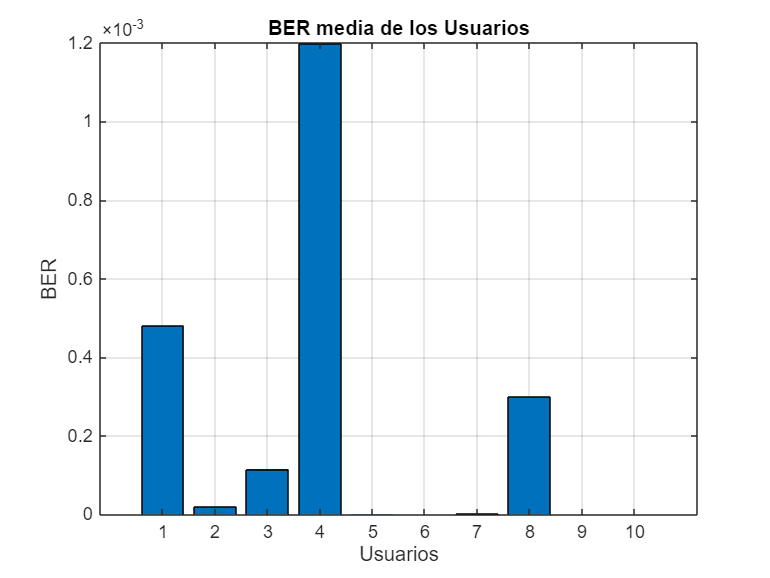

BER_avg = Calculate_BER(SNR_instantanea, M);

% Visualización de la BER media de los usuarios
figure;
bar(BER_avg); % Representación gráfica en barras
title('BER media de los Usuarios');
xlabel('Usuarios');
ylabel('BER');
grid on;

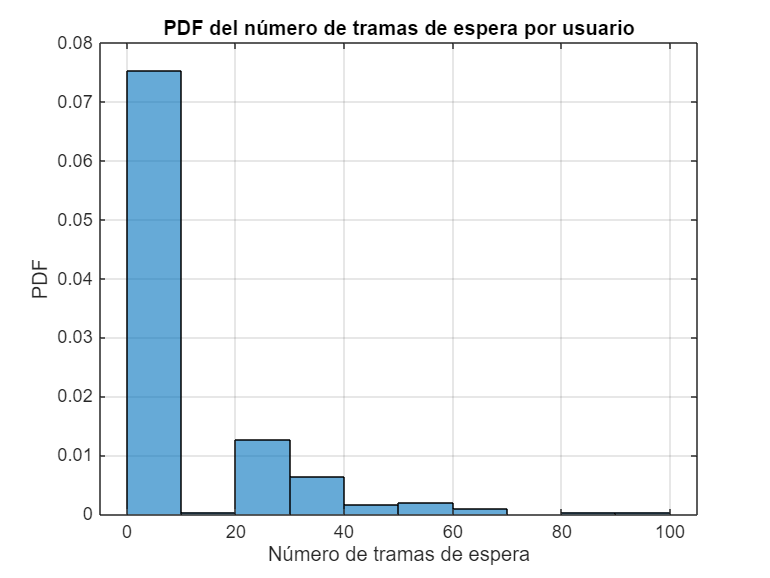

% Generación de bits a transmitir
num_bits = log2(M) * num_muestras; % 4 bits por símbolo
btx = randi([0 1], K, num_bits);

% Transmisión 16QAM
[brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);


% --- PDF del número total de tramas de espera ---
% Convertimos la variable 'retardos' en un solo vector
all_delays = cell2mat(retardos);

% Calculamos el total de tramas de espera sumando todos los retardos
total_tramas_espera = sum(all_delays);

% Representamos la PDF del número de tramas de espera
figure;
histogram(all_delays, 'Normalization', 'pdf');
xlabel('Número de tramas de espera');
ylabel('PDF');
title('PDF del número de tramas de espera por usuario');
grid on;

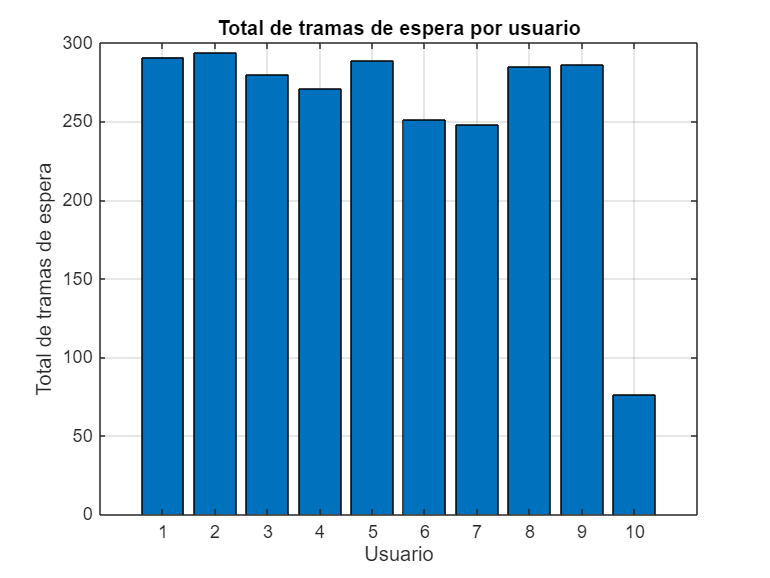

% --- Total de tramas de espera por usuario ---
% Sumamos los retardos para cada usuario (por fila de la celda 'retardos')
total_delays_per_user = cellfun(@sum, retardos);

% Representamos el total de retardos por usuario en un gráfico de barras
figure;
bar(1:K, total_delays_per_user);
xlabel('Usuario');
ylabel('Total de tramas de espera');
title('Total de tramas de espera por usuario');
grid on;

% --- Simulación con frecuencia de Doppler = 50 Hz --
SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(2), num_muestras,ts);

SNR_instantanea =    33.6140   33.6137   33.6133   33.6129   33.6126   33.6122   33.6119   33.6115   33.6111   33.6108   33.6104   33.6100   33.6097   33.6093   33.6089   33.6086   33.6082   33.6079   33.6075   33.6071   33.6068   33.6064   33.6060   33.6057   33.6053   33.6049   33.6046   33.6042   33.6039   33.6035   33.6031   33.6028   38.2305   38.2304   38.2303   38.2303   38.2302   38.2301   38.2300   38.2299   38.2298   38.2297   38.2296   38.2295   38.2294   38.2293   38.2292   38.2291   38.2290   38.2289
   39.7563   39.7560   39.7556   39.7553   39.7550   39.7546   39.7543   39.7540   39.7536   39.7533   39.7529   39.7526   39.7523   39.7519   39.7516   39.7512   39.7509   39.7506   39.7502   39.7499   39.7496   39.7492   39.7489   39.7485   39.7482   39.7479   39.7475   39.7472   39.7468   39.7465   39.7462   39.7458   43.4079   43.4082   43.4084   43.4087   43.4089   43.4092   43.4094   43.4097   43.4099   43.4102   43.4104   43.4107   43.4109   43.4112   43.4114   43.4117 

SNR_instantanea = SNR_instantanea(:, 1:32:end);

SNR_instantanea =    33.6140   38.2305   37.6199   37.5862   36.5889   35.8122   42.8200   37.7317   37.6436   38.9041   45.9833   29.3855   36.9862   32.9944   39.9153   36.2487   37.0560   37.2469   37.1250   24.9958   40.4412   37.3490   46.8857   43.7907   35.1382   27.5387   35.8145   35.8875   47.0804   42.2421   45.0092   38.7638   35.4176   37.1356   38.8813   45.9205   38.1523   36.0382   37.9109   28.6260   41.3132   32.6329   41.0727   37.4114   31.4571   41.9731   43.4369   35.6353   43.7404   42.3833
   39.7563   43.4079   43.7046   40.1262   47.9983   45.0848   36.7592   46.4723   42.3903   31.3592   48.1628   43.3218   49.5499   39.9756   38.6188   43.6814   41.7273   39.1919   42.4690   38.3567   47.6540   49.2509   38.1168   39.4022   32.2543   40.2853   34.7117   44.8319   27.5811   42.0545   32.3065   31.7038   47.1279   45.9428   49.9822   40.0234   49.5320   36.9816   44.1749   47.1271   44.3444   44.4919   45.7648   36.8489   38.1256   45.2768   46.4398   42.0152 

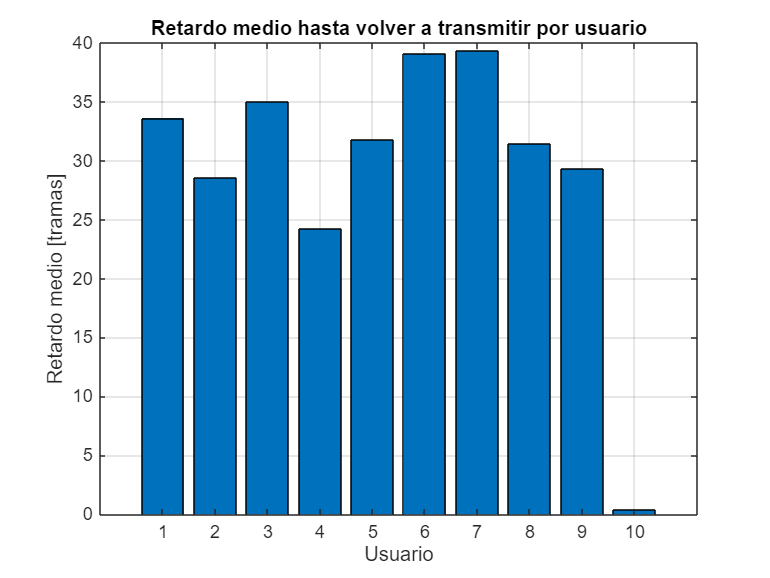


% Llamada al scheduler
[selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
% Dibuja el retardo medio por usuario
plotMeanDelay(retardos);

% Mostrar el resultado final
disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

Usuario seleccionado final: 10      Vector de retardo final: 24   4  96  16   8  20  19  13   1   0


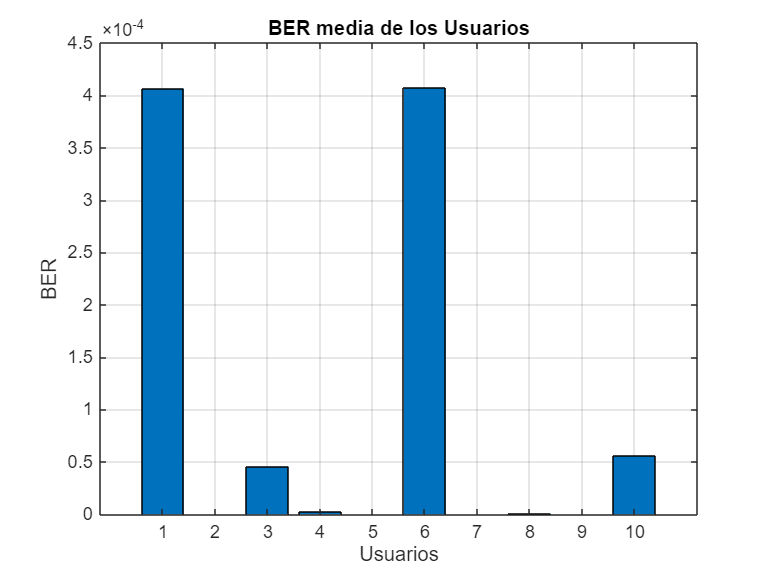

BER_avg = Calculate_BER(SNR_instantanea, M);

% Visualización de la BER media de los usuarios
figure;
bar(BER_avg); % Representación gráfica en barras
title('BER media de los Usuarios');
xlabel('Usuarios');
ylabel('BER');
grid on;

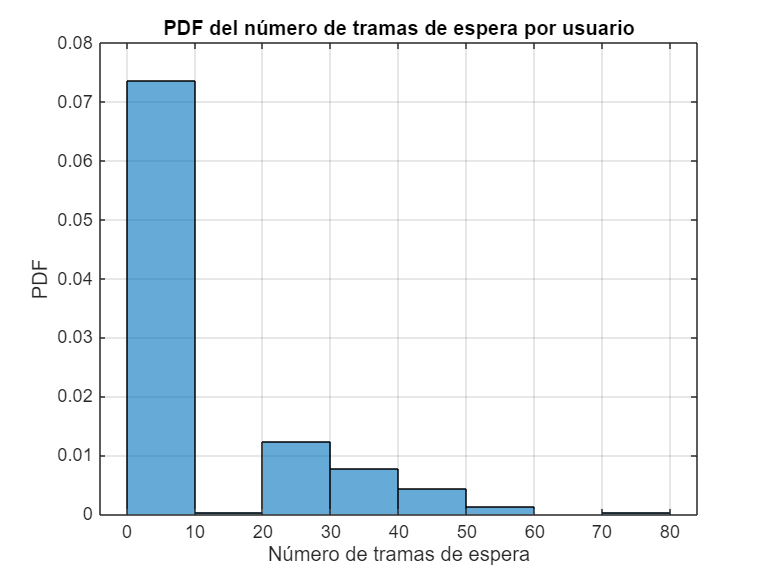

% Generación de bits a transmitir
num_bits = log2(M) * num_muestras; % 4 bits por símbolo
btx = randi([0 1], K, num_bits);

% Transmisión 16QAM
[brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);


% --- PDF del número total de tramas de espera ---
% Convertimos la variable 'retardos' en un solo vector
all_delays = cell2mat(retardos);

% Calculamos el total de tramas de espera sumando todos los retardos
total_tramas_espera = sum(all_delays);

% Representamos la PDF del número de tramas de espera
figure;
histogram(all_delays, 'Normalization', 'pdf');
xlabel('Número de tramas de espera');
ylabel('PDF');
title('PDF del número de tramas de espera por usuario');
grid on;

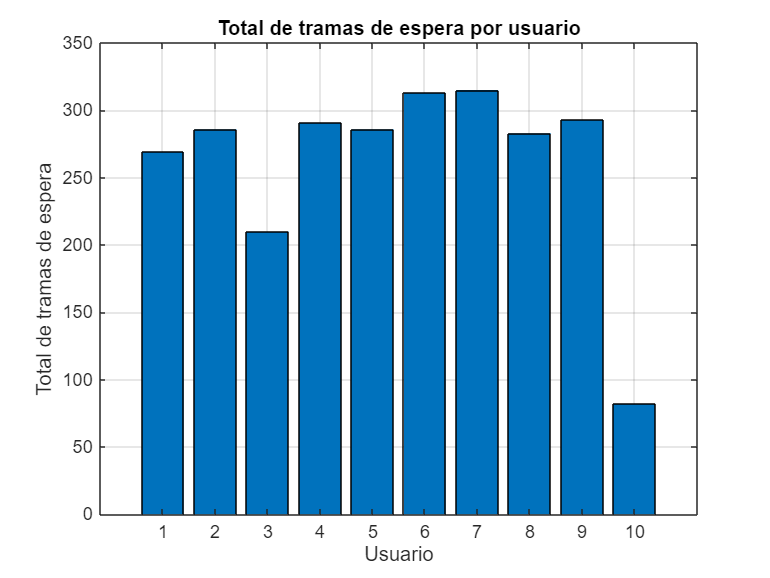

% --- Total de tramas de espera por usuario ---
% Sumamos los retardos para cada usuario (por fila de la celda 'retardos')
total_delays_per_user = cellfun(@sum, retardos);

% Representamos el total de retardos por usuario en un gráfico de barras
figure;
bar(1:K, total_delays_per_user);
xlabel('Usuario');
ylabel('Total de tramas de espera');
title('Total de tramas de espera por usuario');
grid on;

% --- Simulación con frecuencia de Doppler = 120 Hz --
SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(3), num_muestras,ts);

SNR_instantanea =    39.3360   39.3360   39.3361   39.3361   39.3362   39.3362   39.3363   39.3363   39.3364   39.3364   39.3365   39.3365   39.3366   39.3366   39.3366   39.3367   39.3367   39.3368   39.3368   39.3369   39.3369   39.3370   39.3370   39.3371   39.3371   39.3372   39.3372   39.3372   39.3373   39.3373   39.3374   39.3374   42.8808   42.8810   42.8811   42.8812   42.8814   42.8815   42.8816   42.8818   42.8819   42.8820   42.8822   42.8823   42.8825   42.8826   42.8827   42.8829   42.8830   42.8831
   33.1799   33.1766   33.1733   33.1700   33.1666   33.1633   33.1600   33.1567   33.1533   33.1500   33.1467   33.1433   33.1400   33.1367   33.1333   33.1300   33.1266   33.1233   33.1199   33.1166   33.1133   33.1099   33.1066   33.1032   33.0999   33.0965   33.0932   33.0898   33.0864   33.0831   33.0797   33.0764   48.4537   48.4538   48.4539   48.4540   48.4541   48.4542   48.4543   48.4544   48.4544   48.4545   48.4546   48.4547   48.4548   48.4549   48.4550   48.4551 

SNR_instantanea = SNR_instantanea(:, 1:32:end);

SNR_instantanea =    39.3360   42.8808   30.3638   33.2959   42.6656   37.5808   36.6326   40.5149   42.8063   44.8098   44.1417   29.1987   46.7803   42.1518   14.0546   41.3751   39.2927   45.8396   43.8040   43.3327   42.1360   30.9451   40.5767   36.3764   43.3846   32.4296   37.9186   32.5864   37.1664   42.3791   33.6016   42.7073   42.6751   41.6451   37.7847   38.2761   40.6793   46.5228   40.7996   40.8316   43.3113   36.4036   40.5406   41.1743   29.4802   36.6959   42.8547   28.7855   18.3614   43.5838
   33.1799   48.4537   45.9436   41.9633   47.2205   46.4788   46.4694   41.7588   40.7450   40.9187   44.9728   40.8147   47.9717   46.7793   47.2196   45.3585   38.2600   45.1561   43.1315   47.6603   46.5405   38.7018   43.3728   40.4543   45.8607   44.7078   44.9453   48.3930   38.5293   53.4912   32.9988   42.8119   42.9521   40.0718   45.7676   46.5539   49.2817   42.5850   46.0351   46.9136   40.5282   47.5851   36.1639   42.4059   45.0759   49.6469   29.3064   37.4423 

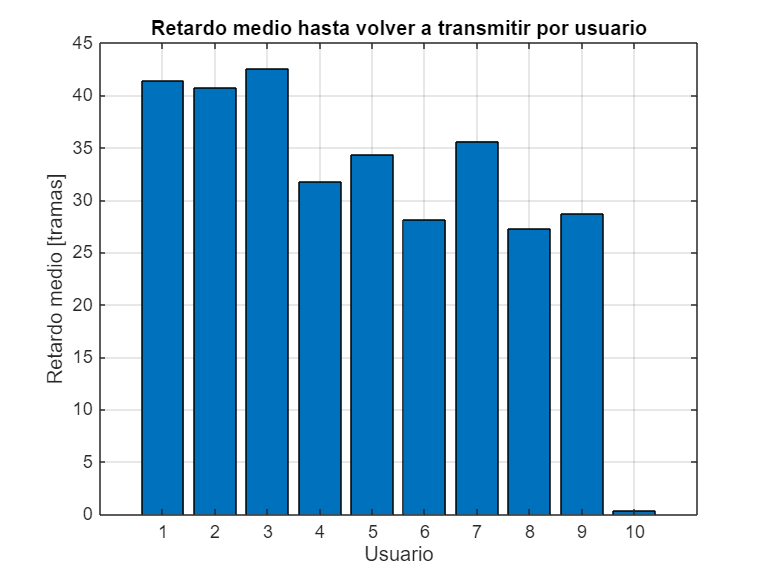


% Llamada al scheduler
[selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
% Dibuja el retardo medio por usuario
plotMeanDelay(retardos);

% Mostrar el resultado final
disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

Usuario seleccionado final: 10      Vector de retardo final: 27  12   4  21  25  29  26   2  34   0


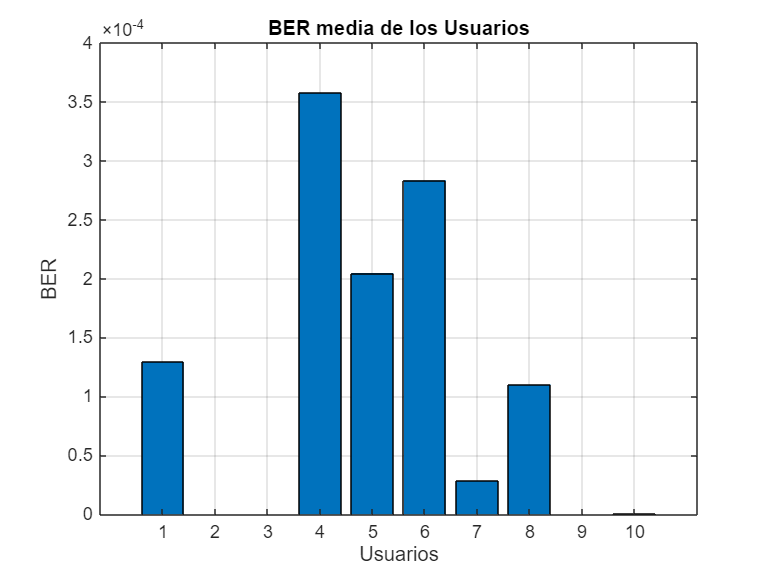

BER_avg = Calculate_BER(SNR_instantanea, M);

% Visualización de la BER media de los usuarios
figure;
bar(BER_avg); % Representación gráfica en barras
title('BER media de los Usuarios');
xlabel('Usuarios');
ylabel('BER');
grid on;

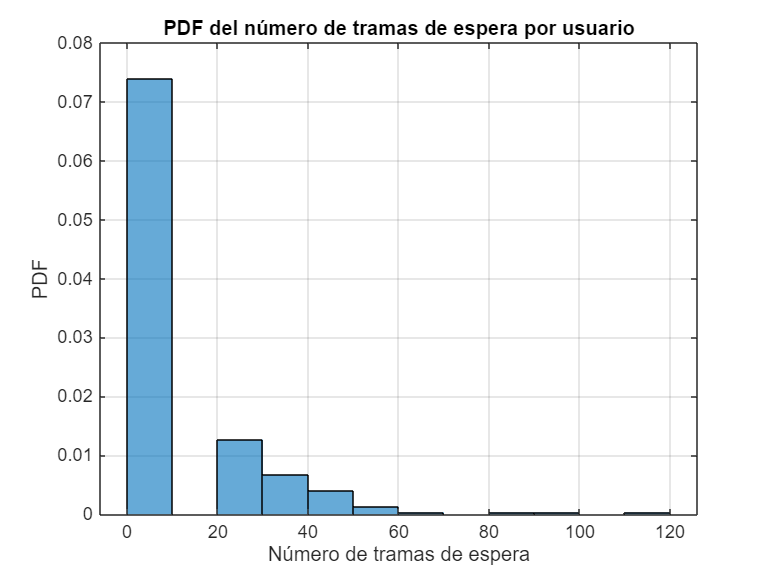

% Generación de bits a transmitir
num_bits = log2(M) * num_muestras; % 4 bits por símbolo
btx = randi([0 1], K, num_bits);

% Transmisión 16QAM
[brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);


% --- PDF del número total de tramas de espera ---
% Convertimos la variable 'retardos' en un solo vector
all_delays = cell2mat(retardos);

% Calculamos el total de tramas de espera sumando todos los retardos
total_tramas_espera = sum(all_delays);

% Representamos la PDF del número de tramas de espera
figure;
histogram(all_delays, 'Normalization', 'pdf');
xlabel('Número de tramas de espera');
ylabel('PDF');
title('PDF del número de tramas de espera por usuario');
grid on;

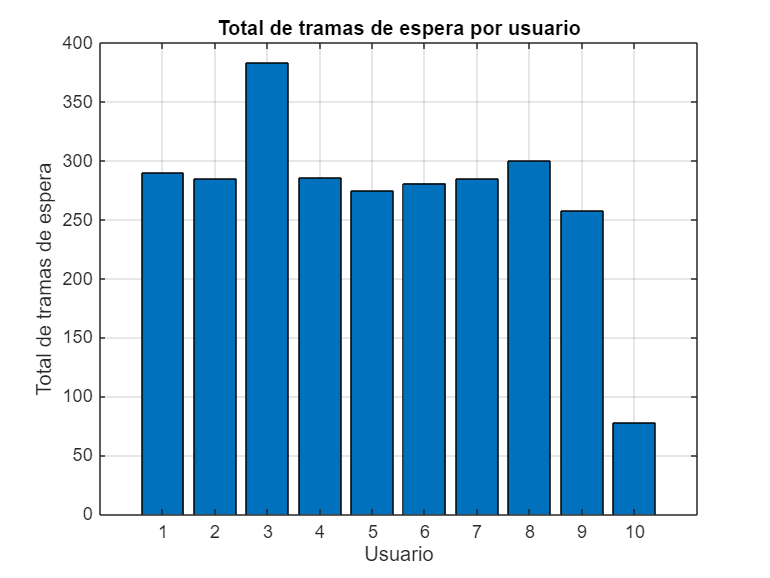

% --- Total de tramas de espera por usuario ---
% Sumamos los retardos para cada usuario (por fila de la celda 'retardos')
total_delays_per_user = cellfun(@sum, retardos);

% Representamos el total de retardos por usuario en un gráfico de barras
figure;
bar(1:K, total_delays_per_user);
xlabel('Usuario');
ylabel('Total de tramas de espera');
title('Total de tramas de espera por usuario');
grid on;

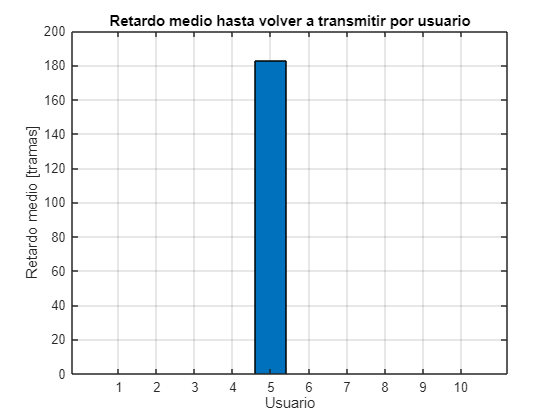

%Casos con algoritmo de maxsnr para las distintas frecuencias Doppler
algoritmo = 'maxsnr';    
% --- Simulación con frecuencia de Doppler = 5 Hz --
SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(1), num_muestras,ts);
SNR_instantanea = SNR_instantanea(:, 1:32:end);

% Llamada al scheduler
[selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
% Dibuja el retardo medio por usuario
plotMeanDelay(retardos);

% Mostrar el resultado final
disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

Usuario seleccionado final: 9      Vector de retardo final: 600  600  600  600   48  600  600  600    0  600


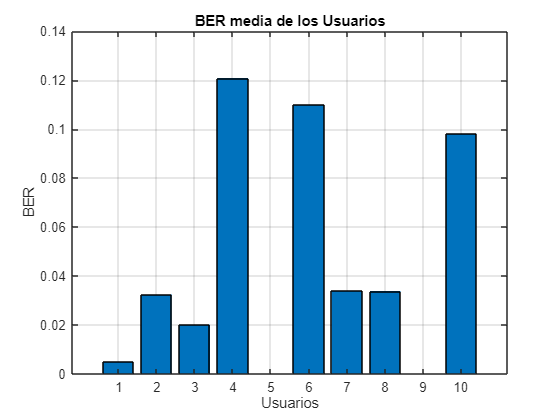


BER_avg = Calculate_BER(SNR_instantanea, M);

% Visualización de la BER media de los usuarios
figure;
bar(BER_avg); % Representación gráfica en barras
title('BER media de los Usuarios');
xlabel('Usuarios');
ylabel('BER');
grid on;

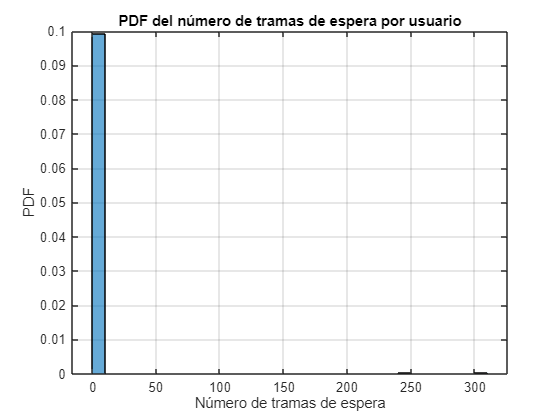

% Generación de bits a transmitir
num_bits = log2(M) * num_muestras; % 4 bits por símbolo
btx = randi([0 1], K, num_bits);

% Transmisión 16QAM
[brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);


% --- PDF del número total de tramas de espera ---
% Convertimos la variable 'retardos' en un solo vector
all_delays = cell2mat(retardos);

% Calculamos el total de tramas de espera sumando todos los retardos
total_tramas_espera = sum(all_delays);

% Representamos la PDF del número de tramas de espera
figure;
histogram(all_delays, 'Normalization', 'pdf');
xlabel('Número de tramas de espera');
ylabel('PDF');
title('PDF del número de tramas de espera por usuario');
grid on;

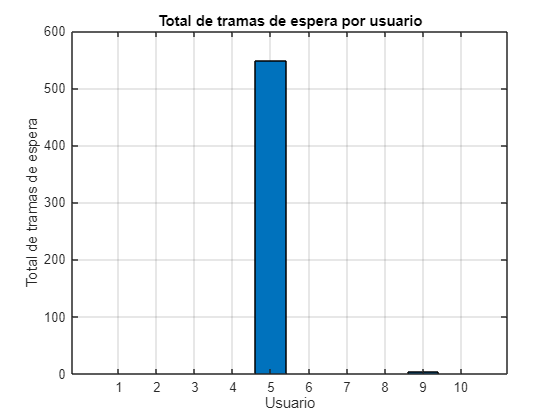

% --- Total de tramas de espera por usuario ---
% Sumamos los retardos para cada usuario (por fila de la celda 'retardos')
total_delays_per_user = cellfun(@sum, retardos);

% Representamos el total de retardos por usuario en un gráfico de barras
figure;
bar(1:K, total_delays_per_user);
xlabel('Usuario');
ylabel('Total de tramas de espera');
title('Total de tramas de espera por usuario');
grid on;

% --- Simulación con frecuencia de Doppler = 50 Hz --
SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(2), num_muestras,ts);

SNR_instantanea =    41.2550   41.2549   41.2548   41.2547   41.2546   41.2545   41.2545   41.2544   41.2543   41.2542   41.2541   41.2540   41.2539   41.2538   41.2537   41.2536   41.2535   41.2534   41.2533   41.2532   41.2531   41.2530   41.2529   41.2528   41.2527   41.2526   41.2525   41.2524   41.2523   41.2522   41.2521   41.2520   38.8004   38.8003   38.8003   38.8002   38.8001   38.8001   38.8000   38.8000   38.7999   38.7998   38.7998   38.7997   38.7996   38.7996   38.7995   38.7995   38.7994   38.7993
   48.6043   48.6042   48.6040   48.6039   48.6037   48.6036   48.6034   48.6033   48.6032   48.6030   48.6029   48.6027   48.6026   48.6024   48.6023   48.6021   48.6020   48.6018   48.6017   48.6015   48.6014   48.6013   48.6011   48.6010   48.6008   48.6007   48.6005   48.6004   48.6002   48.6001   48.5999   48.5998   41.5880   41.5880   41.5880   41.5880   41.5880   41.5880   41.5881   41.5881   41.5881   41.5881   41.5881   41.5881   41.5882   41.5882   41.5882   41.5882 

SNR_instantanea = SNR_instantanea(:, 1:32:end);

SNR_instantanea =    41.2550   38.8004   41.1632   42.9251   29.7653   27.8942   40.2411   33.9412   39.8659   39.0413   41.9322   42.4872   26.3749   31.7646   42.9896   25.8194   31.2807   40.0440   35.2747   38.5072   42.2288   36.8575   38.0752   40.3441   36.6576   33.1022   40.1871   40.5293   39.0963   37.6752   44.0618   40.9537   35.7174   29.5192   34.5798   37.5592   27.6488   46.3930   35.9665   44.2995   39.5870   44.4723   35.8079   38.9408   39.1105   40.9553   35.1320   40.2344   37.2665   35.0956
   48.6043   41.5880   40.5650   43.8292   44.6784   43.7908   45.6615   39.8900   34.2892   46.1604   50.6646   44.5048   44.4173   41.0925   38.1166   40.1741   39.7859   45.7374   45.6645   47.8346   37.5841   46.1319   21.6999   44.7639   36.9352   39.7600   34.6244   47.7100   48.1211   50.9472   48.7755   46.5641   48.1890   52.3234   47.9340   46.6456   45.1327   18.2301   39.5102   26.6601   47.0046   45.1186   37.7848   36.0469   43.0080   39.3633   41.6649   50.6624 

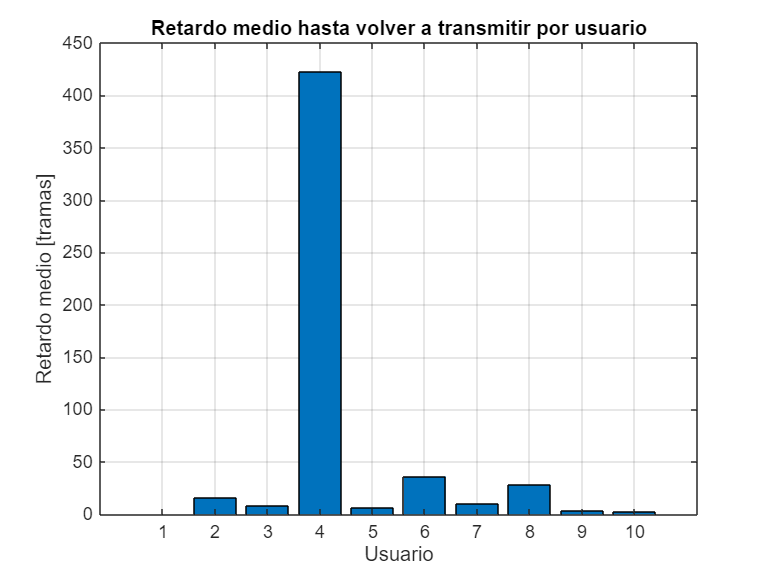


% Llamada al scheduler
[selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
% Dibuja el retardo medio por usuario
plotMeanDelay(retardos);

% Mostrar el resultado final
disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

Usuario seleccionado final: 6      Vector de retardo final: 627   49   32   15   10    0    5   14    2    1


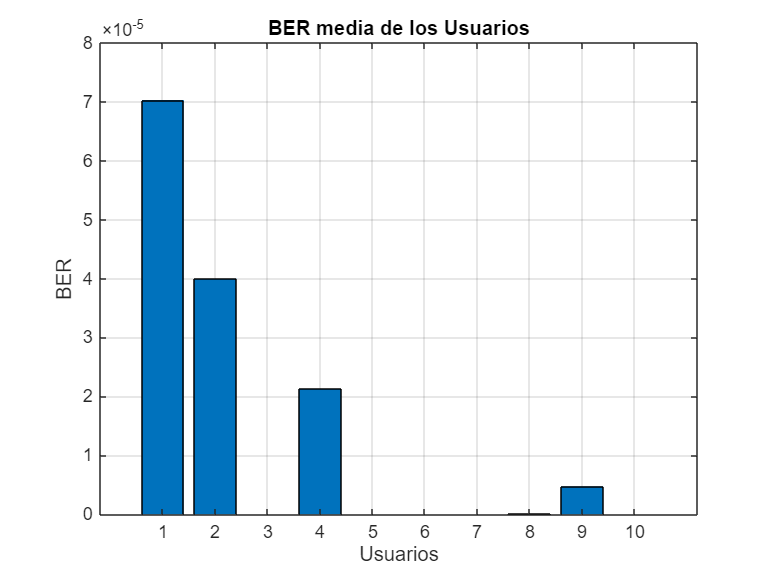



BER_avg = Calculate_BER(SNR_instantanea, M);

% Visualización de la BER media de los usuarios
figure;
bar(BER_avg); % Representación gráfica en barras
title('BER media de los Usuarios');
xlabel('Usuarios');
ylabel('BER');
grid on;

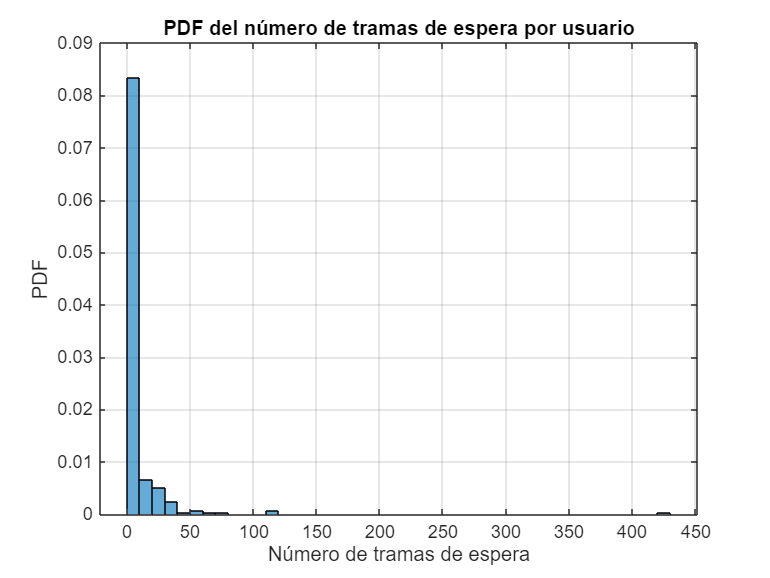

% Generación de bits a transmitir
num_bits = log2(M) * num_muestras; % 4 bits por símbolo
btx = randi([0 1], K, num_bits);

% Transmisión 16QAM
[brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);


% --- PDF del número total de tramas de espera ---
% Convertimos la variable 'retardos' en un solo vector
all_delays = cell2mat(retardos);

% Calculamos el total de tramas de espera sumando todos los retardos
total_tramas_espera = sum(all_delays);

% Representamos la PDF del número de tramas de espera
figure;
histogram(all_delays, 'Normalization', 'pdf');
xlabel('Número de tramas de espera');
ylabel('PDF');
title('PDF del número de tramas de espera por usuario');
grid on;

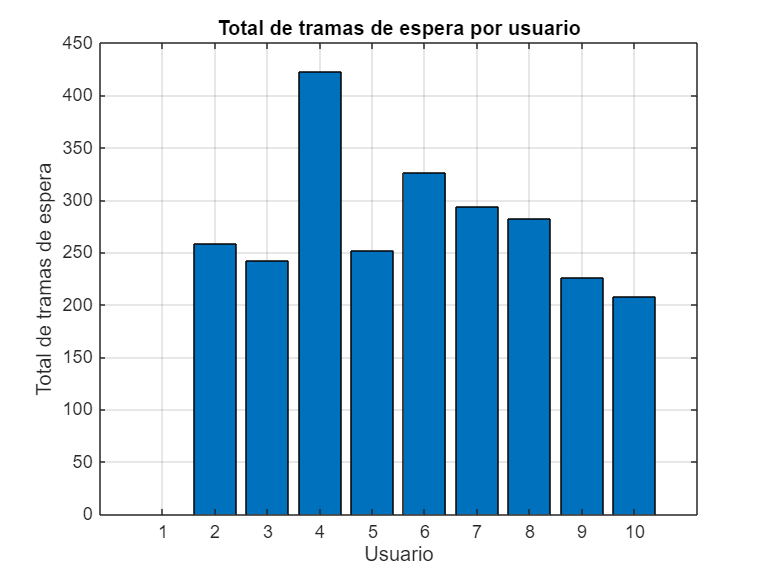

% --- Total de tramas de espera por usuario ---
% Sumamos los retardos para cada usuario (por fila de la celda 'retardos')
total_delays_per_user = cellfun(@sum, retardos);

% Representamos el total de retardos por usuario en un gráfico de barras
figure;
bar(1:K, total_delays_per_user);
xlabel('Usuario');
ylabel('Total de tramas de espera');
title('Total de tramas de espera por usuario');
grid on;

% --- Simulación con frecuencia de Doppler = 120 Hz --
SNR_instantanea = Apply_Rayleigh_Channel(SNRs, fd_values(3), num_muestras,ts)

SNR_instantanea =    32.4556   32.4555   32.4554   32.4552   32.4551   32.4550   32.4549   32.4547   32.4546   32.4545   32.4544   32.4543   32.4542   32.4540   32.4539   32.4538   32.4537   32.4536   32.4535   32.4533   32.4532   32.4531   32.4530   32.4529   32.4528   32.4527   32.4526   32.4525   32.4523   32.4522   32.4521   32.4520   46.6596   46.6598   46.6599   46.6600   46.6601   46.6602   46.6603   46.6604   46.6605   46.6607   46.6608   46.6609   46.6610   46.6611   46.6612   46.6613   46.6614   46.6616
   44.2469   44.2467   44.2465   44.2462   44.2460   44.2458   44.2456   44.2453   44.2451   44.2449   44.2446   44.2444   44.2442   44.2440   44.2437   44.2435   44.2433   44.2431   44.2428   44.2426   44.2424   44.2421   44.2419   44.2417   44.2415   44.2412   44.2410   44.2408   44.2406   44.2403   44.2401   44.2399   44.7277   44.7274   44.7272   44.7269   44.7267   44.7265   44.7262   44.7260   44.7257   44.7255   44.7252   44.7250   44.7248   44.7245   44.7243   44.7240 

SNR_instantanea = SNR_instantanea(:, 1:32:end)

SNR_instantanea =    32.4556   46.6596   33.2380   40.7017   34.0629   24.2792   44.6608   31.9911   42.9152   43.9009   37.0152   38.2445   39.0331   38.8470   37.2377   36.7488   33.9278   40.5089   35.4925   36.4173   42.6666   39.0538   38.2480   29.7447   25.3228   40.1784   41.2878   38.0939   20.5904   40.0692   39.7849   39.8576   46.8774   38.3926   35.1920   29.6693   37.4114   40.1659   39.5026   35.0935   40.0946   41.9820   42.5320   39.0507   28.8850   37.3755   31.7562   15.7863   39.1675   40.4730
   44.2469   44.7277   47.5418   47.8277   48.7261   36.3544   42.4300   46.4114   45.0491   48.5653   46.5379   43.7024   29.0140   38.6695   36.5939   48.3217   35.5639   43.8192   41.9037   43.9299   50.9813   45.1271   47.8808   38.6987   43.9166   46.1855   49.5447   44.6559   44.1056   49.4544   34.4284   42.1787   48.7894   30.8576   41.9987   47.4091   43.8961   35.6322   43.1975   34.9371   46.5357   46.7671   49.1604   41.0382   54.8581   42.9885   38.3974   36.7113 

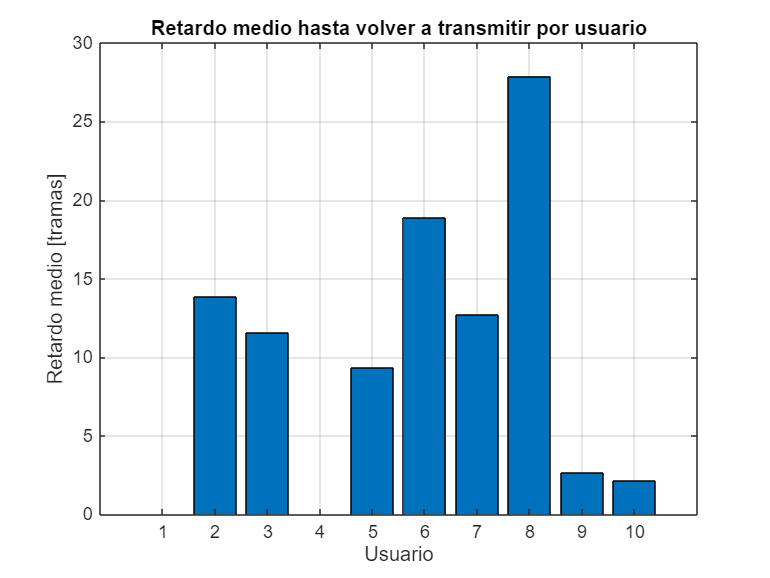


% Llamada al scheduler
[selected_user, selected_users, delay_vector, hist_SNR, retardos, user_tx_count] = Scheduler(SNR_instantanea, delay_vector, SNR_avg, algoritmo, num_tramas);
% Dibuja el retardo medio por usuario
plotMeanDelay(retardos);

% Mostrar el resultado final
disp(['Usuario seleccionado final: ', num2str(selected_user),'      Vector de retardo final: ', num2str(delay_vector)]);

Usuario seleccionado final: 5      Vector de retardo final: 927    8   18  315    0    2    3   54    1    5


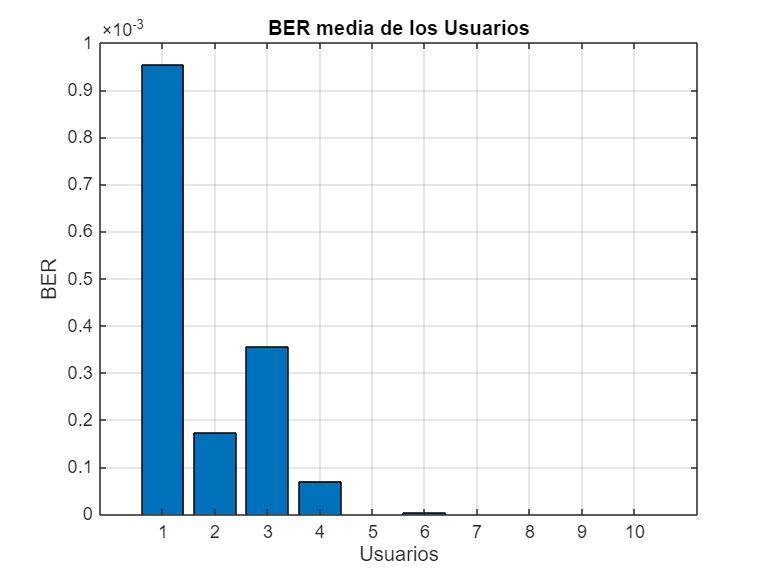


M = 16;
BER_avg = Calculate_BER(SNR_instantanea, M);

% Visualización de la BER media de los usuarios
figure;
bar(BER_avg); % Representación gráfica en barras
title('BER media de los Usuarios');
xlabel('Usuarios');
ylabel('BER');
grid on;

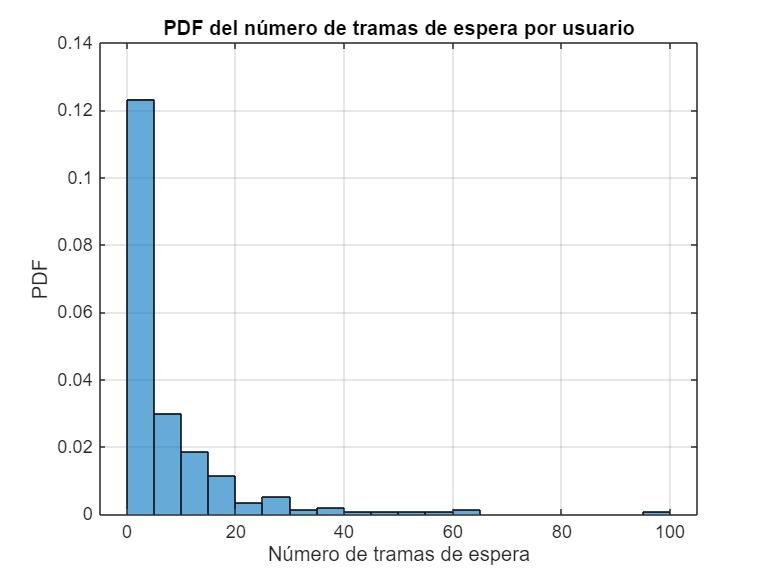

% Generación de bits a transmitir
num_bits = log2(M) * num_muestras; % 4 bits por símbolo
btx = randi([0 1], K, num_bits);

% Transmisión 16QAM
[brx, y] = Transmit_16QAM(btx, selected_users, SNR_instantanea, M);


% --- PDF del número total de tramas de espera ---
% Convertimos la variable 'retardos' en un solo vector
all_delays = cell2mat(retardos);

% Calculamos el total de tramas de espera sumando todos los retardos
total_tramas_espera = sum(all_delays);

% Representamos la PDF del número de tramas de espera
figure;
histogram(all_delays, 'Normalization', 'pdf');
xlabel('Número de tramas de espera');
ylabel('PDF');
title('PDF del número de tramas de espera por usuario');
grid on;

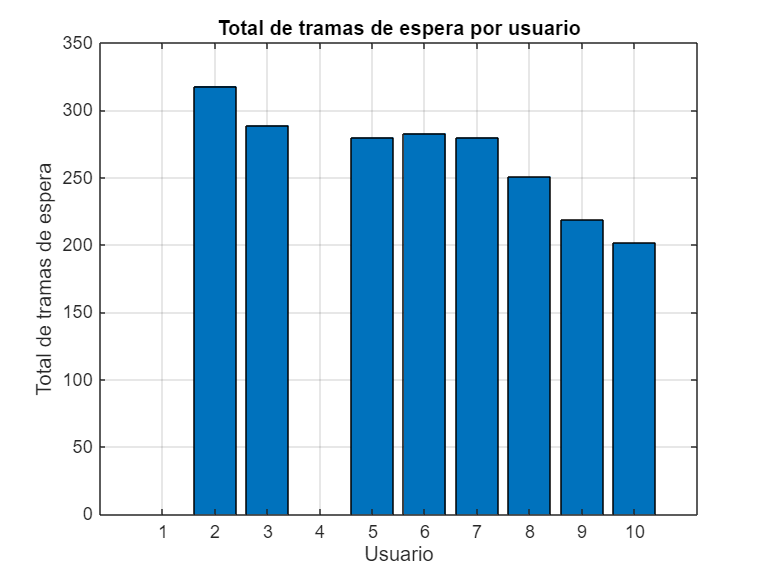

% --- Total de tramas de espera por usuario ---
% Sumamos los retardos para cada usuario (por fila de la celda 'retardos')
total_delays_per_user = cellfun(@sum, retardos);

% Representamos el total de retardos por usuario en un gráfico de barras
figure;
bar(1:K, total_delays_per_user);
xlabel('Usuario');
ylabel('Total de tramas de espera');
title('Total de tramas de espera por usuario');
grid on;